# Transform Body Trajectory into Feet Trajectory

The previous script (DCMTrajectoryGen.mlx) creates the robot's center of mass (COM) trajectory and swing foot trajectories that are defined with respect to the world frame. All the position information is global. What we really want is the position information with respect to the robot's local body frame. because in the end what we are moving are the two feet of the robot. Here we perform a transformation of reference frames to make the body and swing trajectories, which are defined with respect to the global origin, into feet trajectories with respect to the the body (COM). 

Another thing to note is the orientation of the feet. Here will make the robot walk while keeping orientation of the body normal to the ground. Therefore, the feet are always normal to the ground, too. Thus the transformation is done for the position only (orientation is added in the next section). You can change the yaw of the foothold to change the direction of robot walking. Also you can change rotate the body in pitch and roll direction during stance for more stability. For more information about hip strategy, check Benjamin Stephens' [Humanoid Push Recovery for Humanoid Robots with Force Controlled Joints](http://www.cs.cmu.edu/~cga/papers/stephens-hum10.pdf).

*Copyright 2019 The MathWorks, Inc.*

animateOn = true; 

% Load default parameters if previous script wasn't run
if ~exist('stepinfos','var')
    load('defaultstepinfos.mat')
end
footinfos = cell(size(stepinfos));
x_torso = 0.12;
sample_time = 0.01;

## Consecutive Steps

This is the main part of the trajectory.

for idx = 1:length(stepinfos)
    % Check the support mode
    curMode = stepinfos{idx}.mode;
    isLeftSupport = strcmp(curMode, 'singlesupportleft'); 
    isRightSupport = strcmp(curMode, 'singlesupportright'); 
    isDoubleSupport = strcmp(curMode, 'doublesupport'); 
    
    footinfos{idx}.timevec = stepinfos{idx}.timevec;  
    
    if isDoubleSupport
        footposeleft = stepinfos{idx}.footposeleft;
        footposeright = stepinfos{idx}.footposeright;
        footinfos{idx}.footleft = [footposeleft(1); 0; footposeleft(2); 0; footposeleft(3); 0].*ones(6,length(stepinfos{idx}.state)); 
        footinfos{idx}.footright = [footposeright(1); 0; footposeright(2); 0; footposeright(3); 0].*ones(6,length(stepinfos{idx}.state));
    end
    
    if isLeftSupport
        footposeleft = stepinfos{idx}.footposeleft;
        swingabs = stepinfos{idx}.swing; 
        footinfos{idx}.footright = swingabs; 
        footinfos{idx}.footleft = [footposeleft(1); 0; footposeleft(2); 0; footposeleft(3); 0].*ones(6,length(stepinfos{idx}.state));   
    end

    if isRightSupport
        footposeright = stepinfos{idx}.footposeright;
        swingabs = stepinfos{idx}.swing; 
        footinfos{idx}.footleft = swingabs; 
        footinfos{idx}.footright = [footposeright(1); 0; footposeright(2); 0; footposeright(3); 0].*ones(6,length(stepinfos{idx}.state));
    end   
end

## Animate the Foot Trajectory

Set up the plot

hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
hAx2 = axes(hFig);
mcolors = get(gca, 'colororder'); 
stateL = footinfos{1}.footleft; 
stateR = footinfos{1}.footright;
stateCoM = stepinfos{1}.state;
hold on 
hLeftRel = plot3(stateL(1,1),stateL(3,1),stateL(5,1),'Color',mcolors(1,:)); 
hRightRel = plot3(stateR(1,1),stateR(3,1),stateR(5,1),'Color',mcolors(2,:));
hCoMRel = plot3(stateCoM(1,1),stateCoM(3,1),stateCoM(5,1),'Color',mcolors(3,:));
hLeftPoint = plot3([0 stateL(1,1)],[0 stateL(3,1)],[z_robot stateL(5,1)], ...
                     '-o','LineWidth',2,'Color',mcolors(1,:),'MarkerIndices',2,'MarkerSize',8);
hRightPoint = plot3([0 stateR(1,1)],[0 stateR(3,1)],[z_robot stateR(5,1)], ...
                     '-o','LineWidth',2,'Color',mcolors(2,:),'MarkerIndices',2,'MarkerSize',8);
                 
hold off 
view(3)
grid on
axis equal 
title('End Effector (Feet) Trajectory')
axis([-0.2*z_robot 3*z_robot -z_robot z_robot -0.2*z_robot 1.2*z_robot])
legend('Left Foot Traj', 'Right Foot Traj', 'Left Foot', 'Right Foot',...
       'Location','northeast'); 

Animation loop

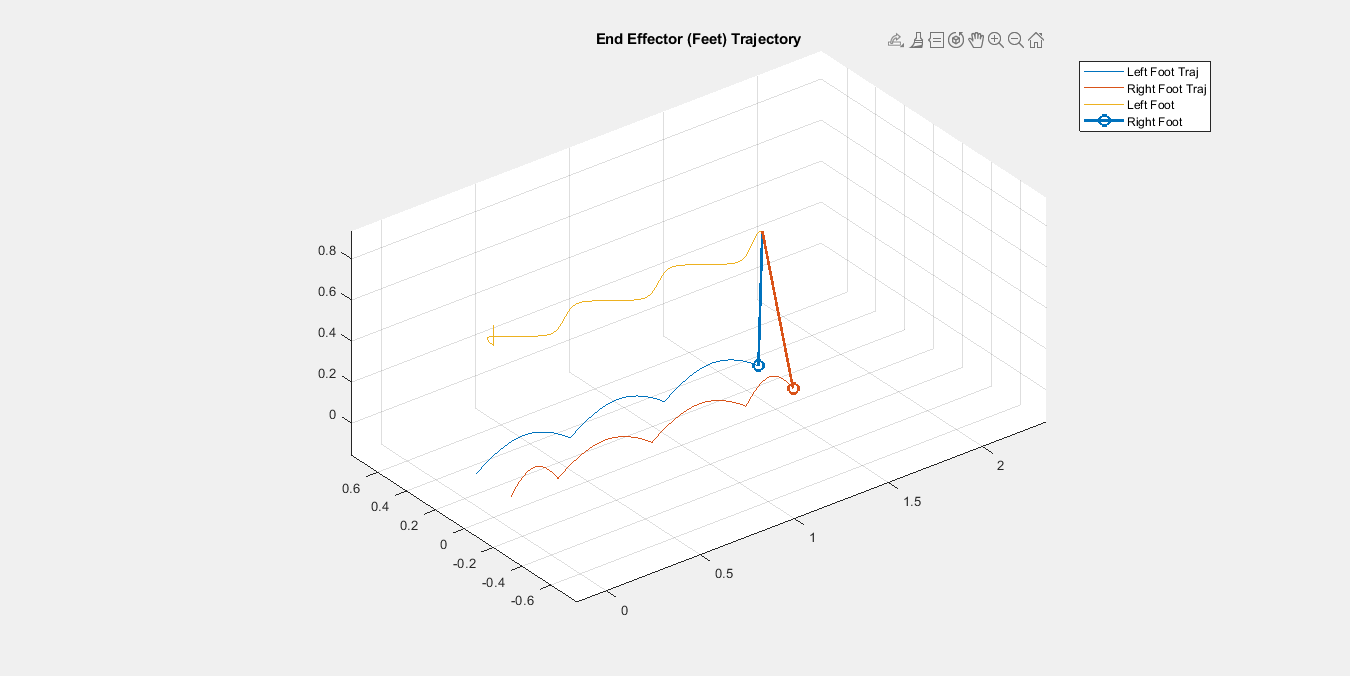

for footidx = 1:length(footinfos)
    stateL = footinfos{footidx}.footleft;
    stateR = footinfos{footidx}.footright;
    stateCoM = stepinfos{footidx}.state;
    for sidx = 1:size(stateL,2)
        appendLine(hLeftRel, stateL([1,3,5],sidx)); 
        appendLine(hRightRel, stateR([1,3,5],sidx));
        appendLine(hCoMRel, stateCoM([1,3,5],sidx));
        updateLine(hLeftPoint, [stepinfos{footidx}.state([1,3,5],sidx) stateL([1,3,5],sidx)]); 
        updateLine(hRightPoint, [stepinfos{footidx}.state([1,3,5],sidx) stateR([1,3,5],sidx)]); 
        
        if animateOn
            pause(0.005);
        end 
    end 
end

## Helper Functions  

Adds points to a graphics line object

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end
